# SID - Demo

This is a demo script for the SID algorithm ([Nöbauer & Skocek et al. 2017](https://doi.org/10.1038%2Fnmeth.4341)). The demo will perform the main steps of the SID algorithm, and give explanations and illustrations of expected results.

Start by loading the demo movie into the workspace:

load('demo_struct.mat');
SID_output.movie_size = demo_struct.movie_size;
SID_output.microlenses = demo_struct.microlenses;
sensor_movie = demo_struct.movie;
clear demo_struct;

## Background-subtracted standard-deviation image

Compute the spatial and temporal background, as well as the standard deviation image and plot them:

Input.bg_iter = 2;
[SID_output.bg_spatial, SID_output.bg_temporal] = ...
    rank_1_factorization(sensor_movie,Input.bg_iter);
SID_output.std_image = ...
    compute_std_image(sensor_movie,SID_output.bg_spatial, SID_output.bg_temporal);

SID_output.bg_spatial = reshape(SID_output.bg_spatial ,SID_output.movie_size(1:2));
SID_output.std_image = reshape(SID_output.std_image, SID_output.movie_size(1:2));

imagesc(SID_output.bg_spatial); axis image; colorbar; title('Spatial background');
plot(SID_output.bg_temporal); title('Temporal background');
imagesc(SID_output.std_image, ...
    [prctile(SID_output.std_image(:), 0) prctile(SID_output.std_image(:), 100.0)]);
title('Stddev image');
axis image;
axis ij;
colorbar;

## De-trend

We can see a trend in the temporal background component *bg_temporal.* To avoid an influence of this trend on subsequent steps it is recommended to divide out the trend:

smooth_window_span = 800;

SID_output.baseline = smooth(SID_output.bg_temporal, smooth_window_span, 'sgolay', 3);
sensor_movie = sensor_movie./SID_output.baseline';
sensor_movie = sensor_movie/max(sensor_movie(:));

plot(SID_output.baseline); title('Frame means (post bg subtract), raw + trend fit');
hold on; plot(SID_output.bg_temporal); hold off

## Low-rank-non-negative-matrix factorization

Input.nnmf_opts.rank = 10;
Input.nnmf_opts.max_iter = 100;
Input.nnmf_opts.lamb_orth_L1 = 1;
Input.nnmf_opts.ini_method='pca';
Input.nnmf_opts.active=SID_output.microlenses>0;
p=0.8;

[SID_output.S, SID_output.T]=fast_NMF(max(sensor_movie-quantile(reshape(...
    sensor_movie(SID_output.microlenses==0,:),1,[]),p),0),Input.nnmf_opts);

Elapsed time is 9.833823 seconds.



SID_output.S=SID_output.S(:,~isoutlier(sum(SID_output.S,1)))';

Let us plot the components of the non-negative matrix factorization:

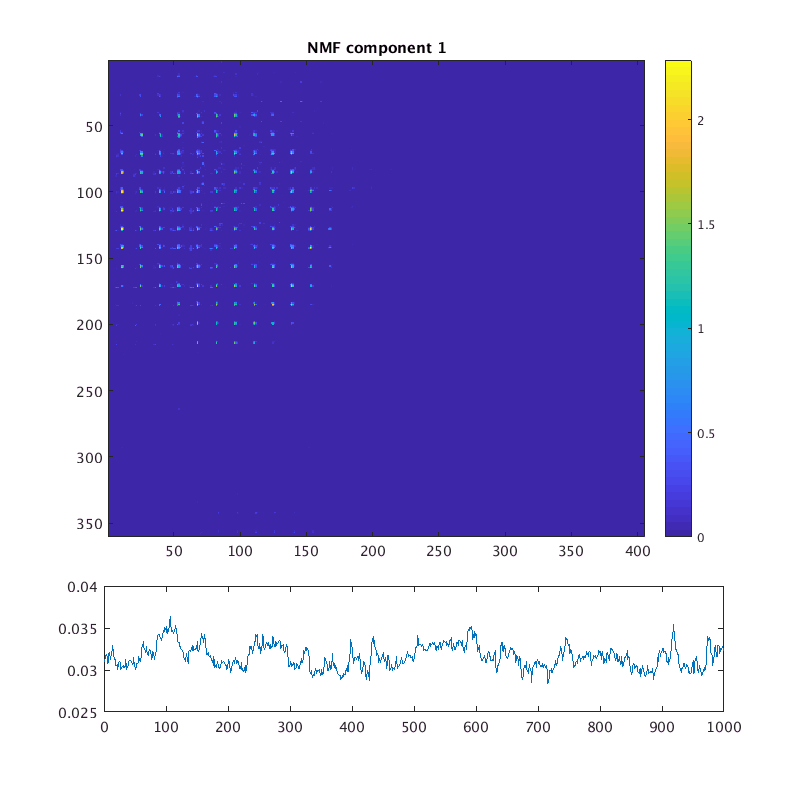

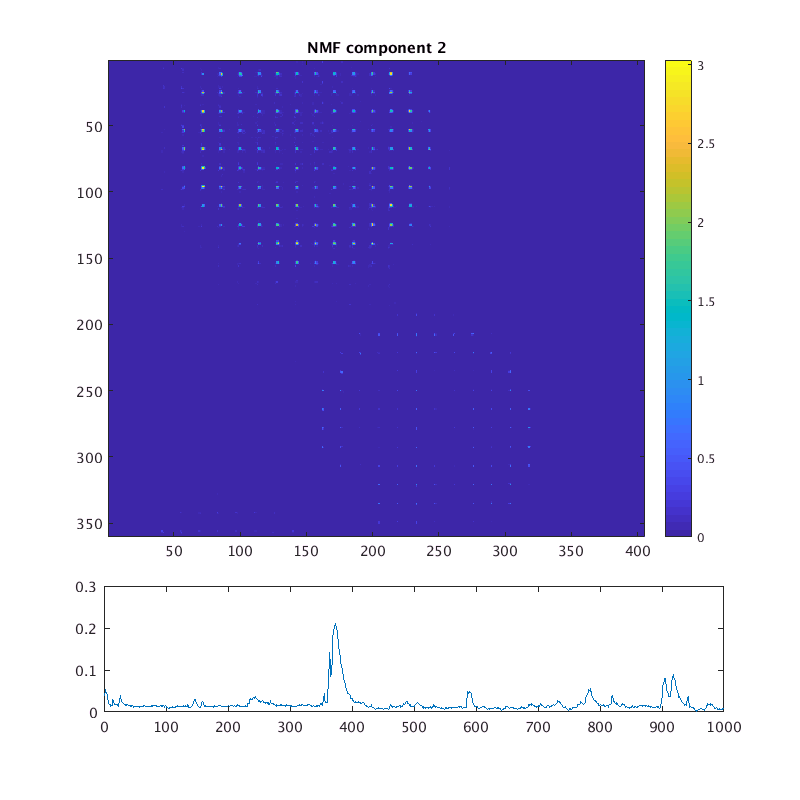

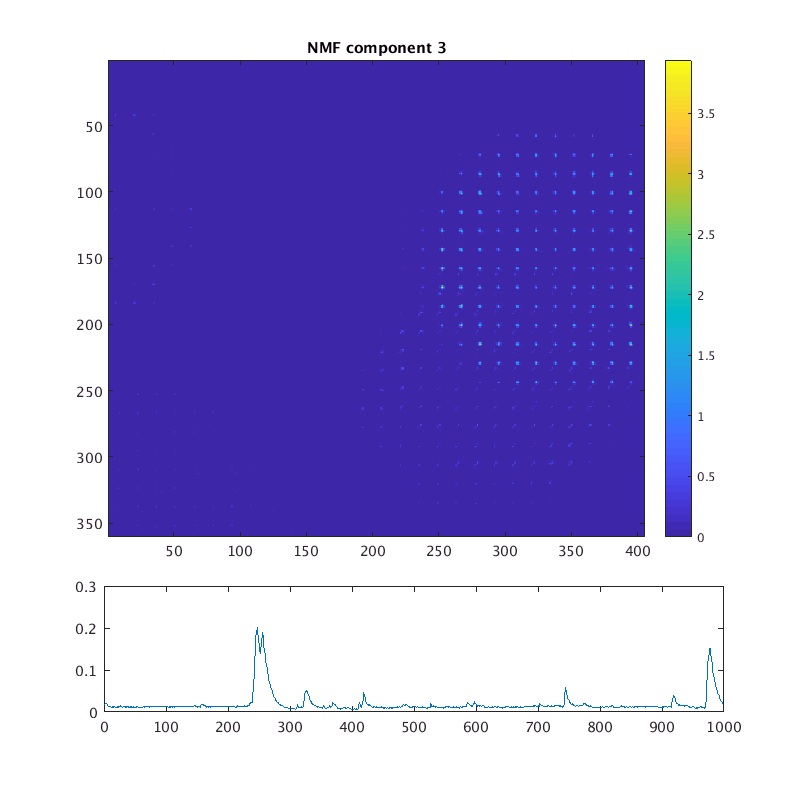

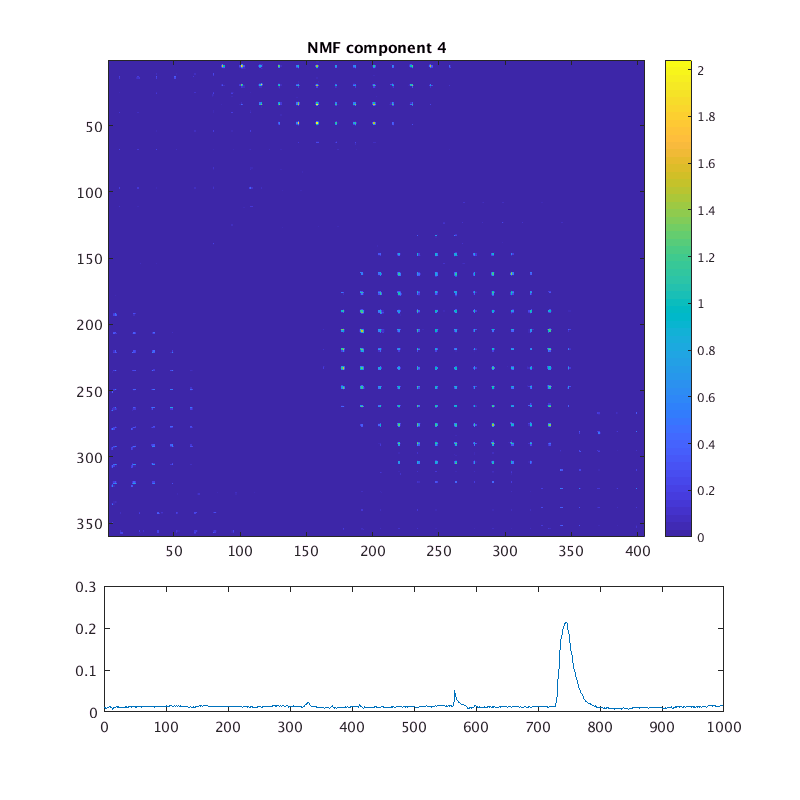

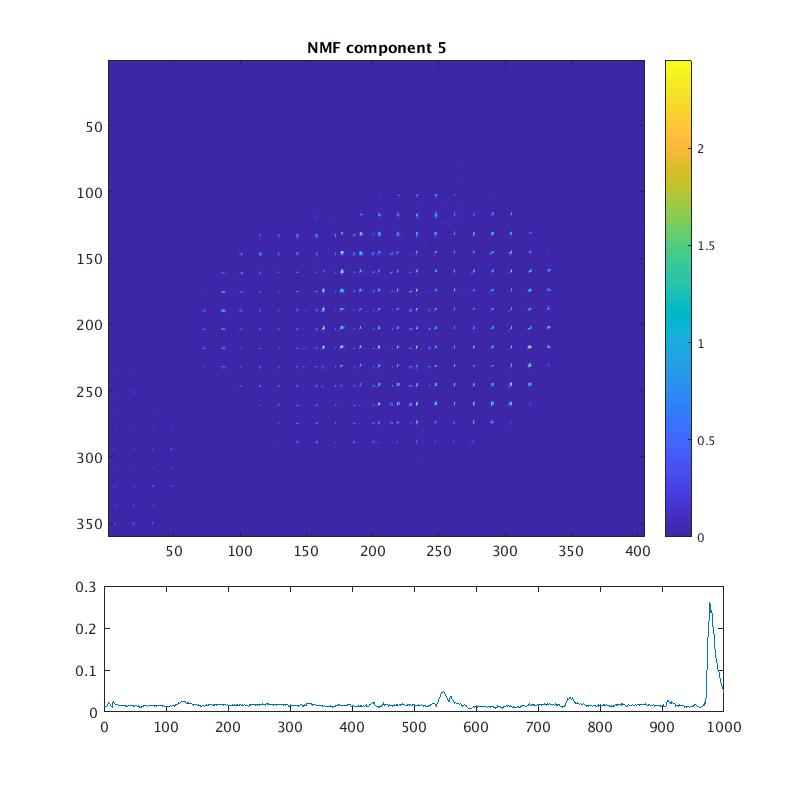

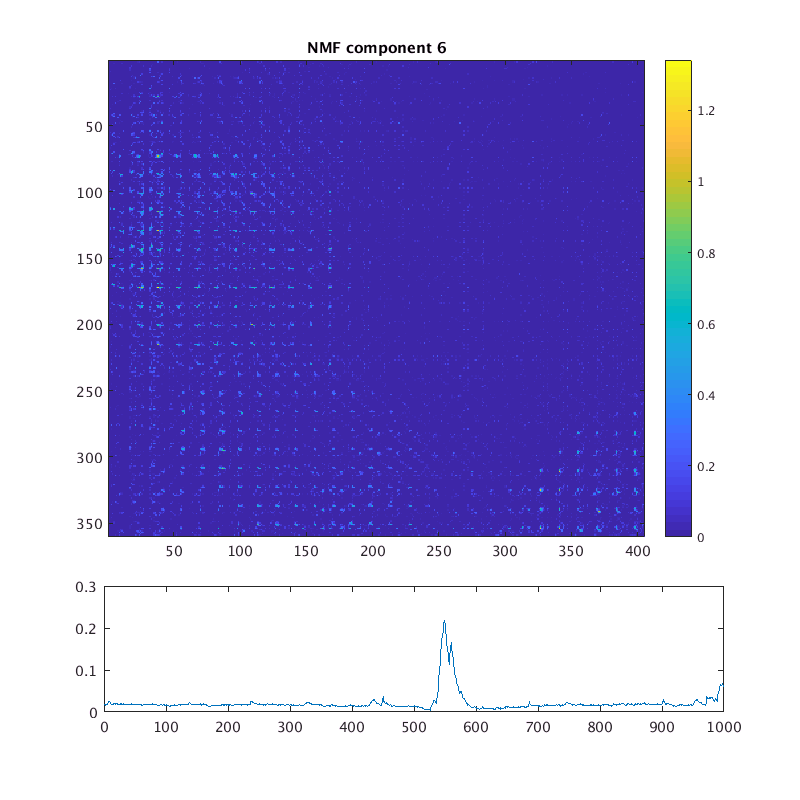

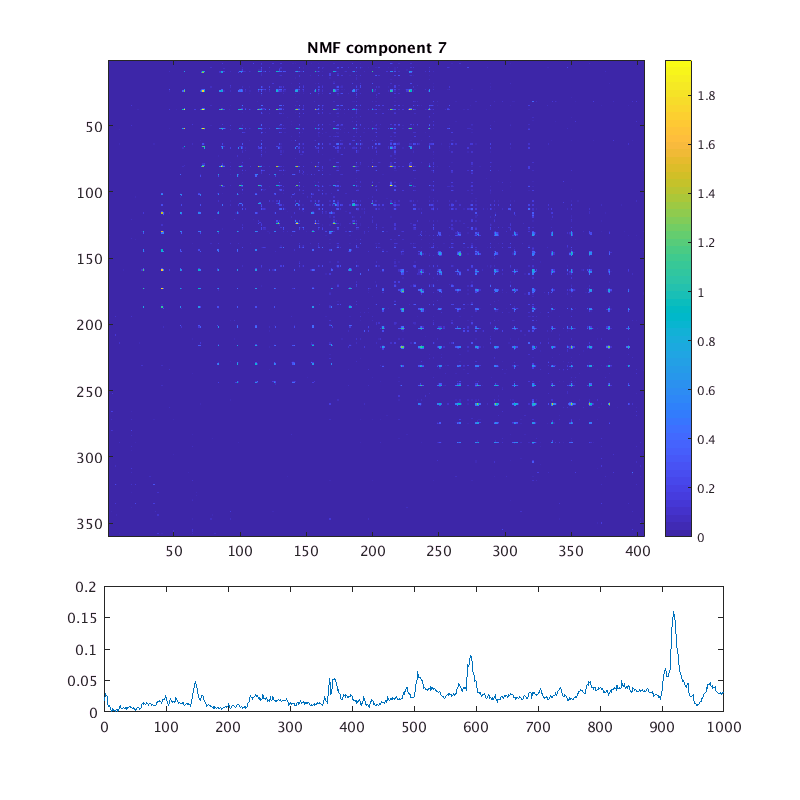

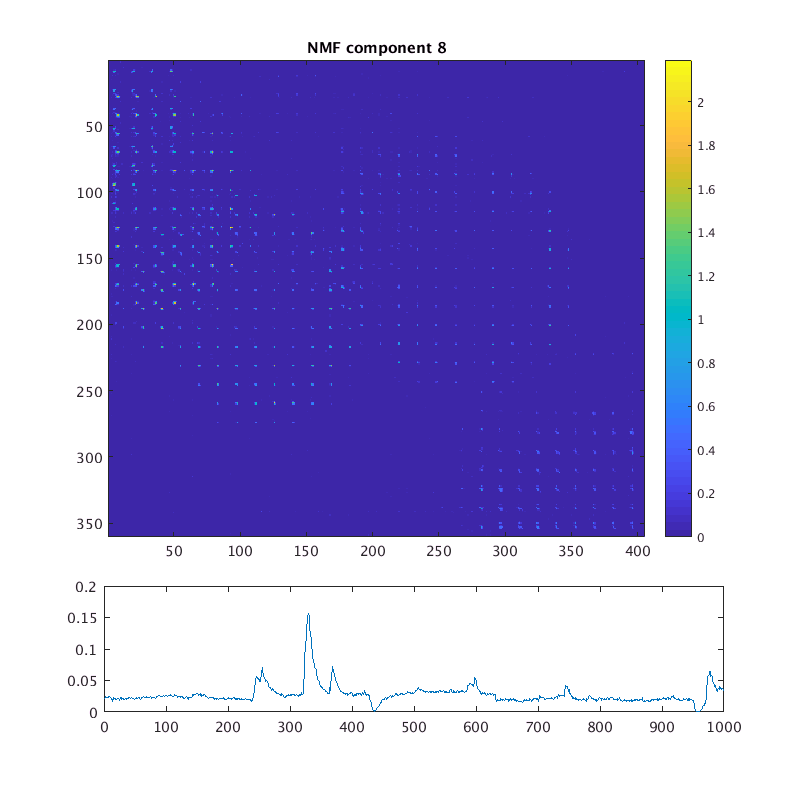

timestr = datestr(now, 'YYmmddTHHMM');
for i=1:size(SID_output.S, 1)
    figure( 'Position', [100 100 800 800]);
    subplot(4,1,[1,2,3]);
    imagesc(reshape(SID_output.S(i,:), size(SID_output.std_image))); 
    axis image; colormap('parula'); colorbar;
    title(['NMF component ' num2str(i)]);
    subplot(4,1,4);
    plot(SID_output.T(i,:));
end